## Task 3

% 3.a.
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = 1500;                            % Values for packet rate in pps
f = 10000;                                % Queue size(in bytes)

N = 20;                                   % number of simulation
n = [10, 20, 30, 40];                     % number of adidional VoIP packets flows

pkt_delay_voip = zeros(1, length(lambda));
error_delay_voip = zeros(1, length(lambda));
pkt_loss_voip = zeros(1, length(lambda)); 
error_loss_voip = zeros(1, length(lambda)); 

pkt_delay_data = zeros(1, length(lambda));
error_delay_data = zeros(1, length(lambda));
pkt_loss_data = zeros(1, length(lambda));  
error_loss_data = zeros(1, length(lambda));  

AVERAGE = zeros(4,4);
TERM = zeros(4,4);

for j = 1:length(n)
    PLd = zeros(1, N);
    PLv = zeros(1, N);
    APDd = zeros(1, N);
    APDv = zeros(1, N);
    MPDd = zeros(1, N);
    MPDv = zeros(1, N);
    TT = zeros(1, N);
    
    for i = 1:N
        [PLd(i), PLv(i), APDd(i), APDv(i), MPDd(i), MPDv(i), TT(i)] = Simulator3(lambda,C,f,P,n(j));
    end    
    alfa = 0.1; % 90% confidence interval 
    
    
    AVERAGE = mean(PLd);
    TERM = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    fprintf("Packet Loss (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_data(j) = AVERAGE;
    error_loss_data(j) = TERM;

    AVERAGE = mean(APDd);
    TERM = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    fprintf("Av. Packet Delay Data (ms)  = %.2e +- %.2e\n\n\n", AVERAGE, TERM);
    pkt_delay_data(j) = AVERAGE;
    error_delay_data(j) = TERM;

    AVERAGE = mean(PLv);
    TERM = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    fprintf("Packet Loss VoIP (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_voip(j) = AVERAGE;
    error_loss_voip(j) = TERM;

    AVERAGE = mean(APDv);
    TERM = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    fprintf("Av. Packet Delay VoIP (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay_voip(j) = AVERAGE;
    error_delay_voip(j) = TERM;
 
end

Packet Loss (%)  = 2.23e-01 +- 1.21e-02


Av. Packet Delay Data (ms)  = 2.01e+00 +- 1.43e-02




Packet Loss VoIP (%)  = 2.69e-02 +- 5.54e-03


Av. Packet Delay VoIP (ms)  = 1.60e+00 +- 1.31e-02


Packet Loss (%)  = 4.30e-01 +- 1.82e-02


Av. Packet Delay Data (ms)  = 2.34e+00 +- 1.52e-02




Packet Loss VoIP (%)  = 5.37e-02 +- 8.17e-03


Av. Packet Delay VoIP (ms)  = 1.94e+00 +- 1.43e-02


Packet Loss (%)  = 7.76e-01 +- 3.18e-02


Av. Packet Delay Data (ms)  = 2.71e+00 +- 1.90e-02




Packet Loss VoIP (%)  = 9.94e-02 +- 7.39e-03


Av. Packet Delay VoIP (ms)  = 2.33e+00 +- 1.92e-02


Packet Loss (%)  = 1.42e+00 +- 4.72e-02


Av. Packet Delay Data (ms)  = 3.27e+00 +- 2.29e-02




Packet Loss VoIP (%)  = 1.77e-01 +- 9.75e-03


Av. Packet Delay VoIP (ms)  = 2.91e+00 +- 2.16e-02


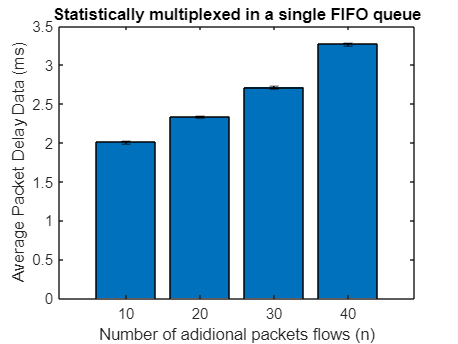



% Plot the results
figure(1)
bar(categorical(n), pkt_delay_data)
title("Statistically multiplexed in a single FIFO queue")
xlabel("Number of adidional packets flows (n)")
ylabel("Average Packet Delay Data (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_data, error_delay_data, error_delay_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

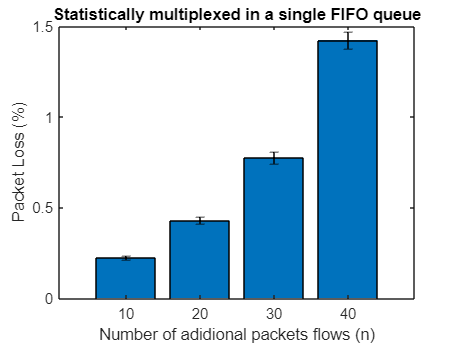


%%% Plot the results
figure(2)
bar(categorical(n), pkt_loss_data)
title("Statistically multiplexed in a single FIFO queue")
xlabel("Number of adidional packets flows (n)")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_data, error_loss_data, error_loss_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

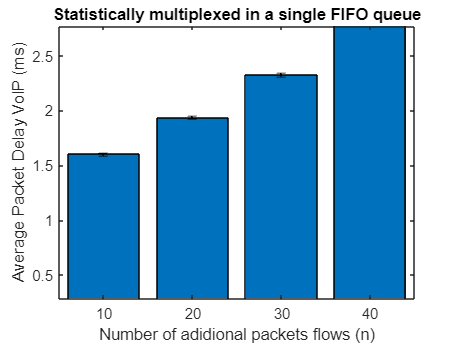


% Plot the results
figure(3)
bar(categorical(n), pkt_delay_voip)
title("Statistically multiplexed in a single FIFO queue")
xlabel("Number of adidional packets flows (n)")
ylabel("Average Packet Delay VoIP (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_voip, error_delay_voip, error_delay_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

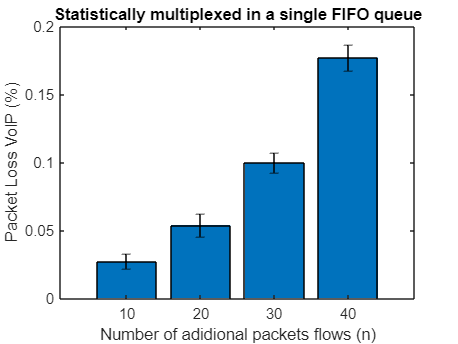


%%% Plot the results
figure(4)
bar(categorical(n), pkt_loss_voip)
title("Statistically multiplexed in a single FIFO queue")
xlabel("Number of adidional packets flows (n)")
ylabel("Packet Loss VoIP (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_voip, error_loss_voip, error_loss_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

%%% conclusão: sem a presença de erros incluido no simulador, as perdas
%%% têm uma percentagem menor e por conseguinte a fila tem um delay menor.